# Calculation of the MTF of a lens

The following lens is to be investigated: micro projection lens Linos F44/4,5, order #: G038846000

Specification according to  data sheet:

- Effective focal length f'=44mm

- F-Number (f/#) k=4,5

- Field angle (2w) 44°

- m=1:14

## Optical data of the lens

addpath(genpath([userpath '\documented'])) % Add folder and all subfolders of RTTB to search path

% Number of surfaces (including sensor surface)        
linos_f44.n_surf=8;
% Curvatures of lens surfaces:
linos_f44.c=[1/14.1;  0;  1/-29.6; 1/13.0; 1/-91.1;  1/14.57;  1/-21; 0];
% Distances from surface to surface:
linos_f44.d=[10;  2.76;  1.94;  1.49;  1.9;  1.07;  2.9;  38.19];
% Glasses (Schott): SK4;  F8;  KZFN2;  LAK31;
% Refraction indices at specified wavelengths:
linos_f44.la=0.00053; % wavelength of lab experiment
linos_f44.n=[1.0; 1.6163353; 1.0; 1.6007627; 1.0; 1.5329841; 1.7010020; 1.0];
% Typ of surface (a=0: spherical surface):
linos_f44.a=[0; 0; 0; 0; 0; 0; 0; 0;];
% Heights of surfaces
linos_f44.h=[5.5;  5.5;  5.0; 5.0;  5.5;  5.5;  5.5;  16.77];
% Max. field angle
linos_f44.w=22*pi/180;

% Position of the stop
d_stop=sum(linos_f44.d(1:4))+0.64; % data sheet: sum(linos_f44.d(1:4))
h_stop=4.07; % data sheet: 4.04

% Calculate entrance pupil from stop
[linos_f44.d_P, linos_f44.l_P]=find_EP(linos_f44.n_surf, linos_f44.d, linos_f44.c, linos_f44.n, d_stop, h_stop);

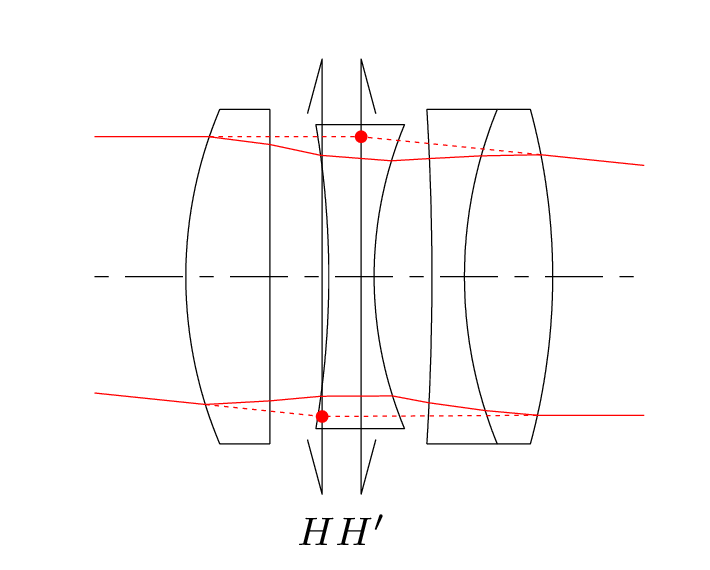

For details on glasses see [ch. 1.2.3 Vertiefung: Eigenschaften optischer Kunststoffe](https://ilias.hs-heilbronn.de/goto.php?target=pg_8357_67103&client_id=iliashhn)

For details on aspheric surfaces see [ch. 4.5.2.3 Beschreibung der Form](https://ilias.hs-heilbronn.de/goto.php?target=pg_8337_67103&client_id=iliashhn)

#### Paraxial data of the lens

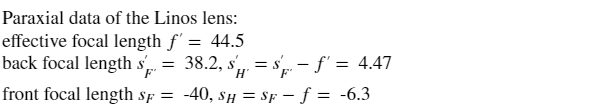

[efl_linos_f44, bfl_linos_f44, ffl_linos_f44]=par_data_basic(linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n);
s_H=bfl_linos_f44-efl_linos_f44;
s_H_q=ffl_linos_f44+efl_linos_f44;

figure('Position',[1 1 500 90]), set(gca,'position',[0 0 1 1]), axis off
text(0,0,...
    {'Paraxial data of the Linos lens:' ...
    ['effective focal length $f'' =$ ' num2str(efl_linos_f44,3)] ...
    ['back focal length $s''_{F''} =$ ' num2str(bfl_linos_f44,3) ', $s''_{H''}=s''_{F''}-f'' =$ ' num2str(s_H_q,3)] ...
    ['front focal length $s_{F} =$ ' num2str(ffl_linos_f44,3) ', $s_{H}=s_{F}-f =$ ' num2str(s_H,3)]}, ...
    'VerticalAlignment', 'bottom', 'FontSize',12,'Interpreter', 'latex')

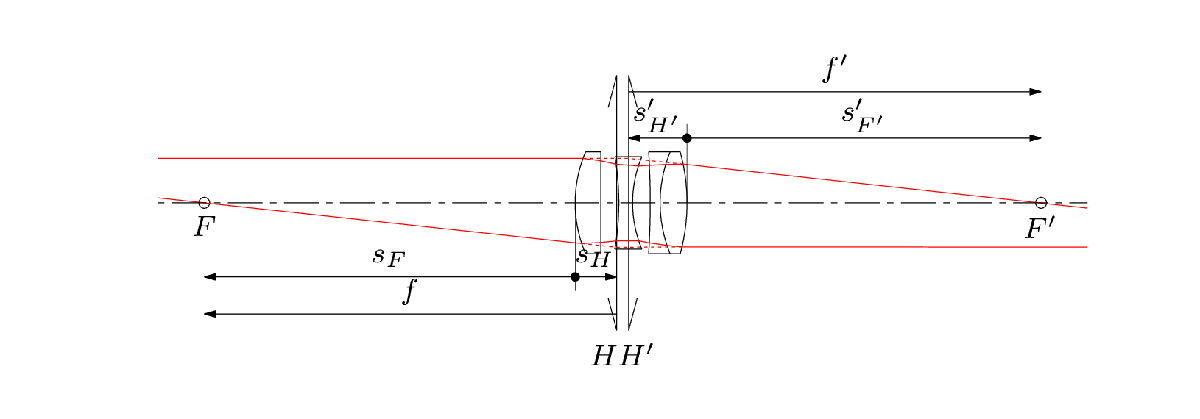

For details on principal planes, back focal length, etc. see [ch. 4.3.1 Brennweite](https://ilias.hs-heilbronn.de/goto.php?target=pg_8337_67103&client_id=iliashhn), 

For details on focal point, basics of imaging, etc. see [ch. 4.1 Einführung Abbildung](https://ilias.hs-heilbronn.de/goto.php?target=pg_8367_67103&client_id=iliashhn)

#### Other basic lens data

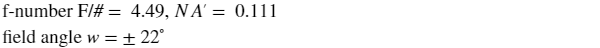

NA_q= linos_f44.l_P/efl_linos_f44;
figure('Position',[1 1 500 40]), set(gca,'position',[0 0 1 1]), axis off
text(0,0,...
    {'Data of the Linos lens:' ...
    ['f-number F$/\# =$ ' num2str(efl_linos_f44/2/linos_f44.l_P,3) ', $NA''=$ ' num2str(NA_q,3) ],...
    ['field angle $w = \pm$ ' num2str(linos_f44.w/pi*180,3) '$^\circ$']},...
    'VerticalAlignment', 'bottom', 'FontSize',12,'Interpreter', 'latex')

For details on numerical aperture see [ch. 4.3.3 Aperturwinkel und Numerische Apertur](https://ilias.hs-heilbronn.de/goto.php?target=pg_8325_67103&client_id=iliashhn)

For details on f-number see [ch. 4.3.4 Blendenzahl](https://ilias.hs-heilbronn.de/goto.php?target=pg_8343_67103&client_id=iliashhn)

For details on field angle see [ch. 4.3.5 Feld und Feldwinkel](https://ilias.hs-heilbronn.de/goto.php?target=pg_8375_67103&client_id=iliashhn)

### Display of the system

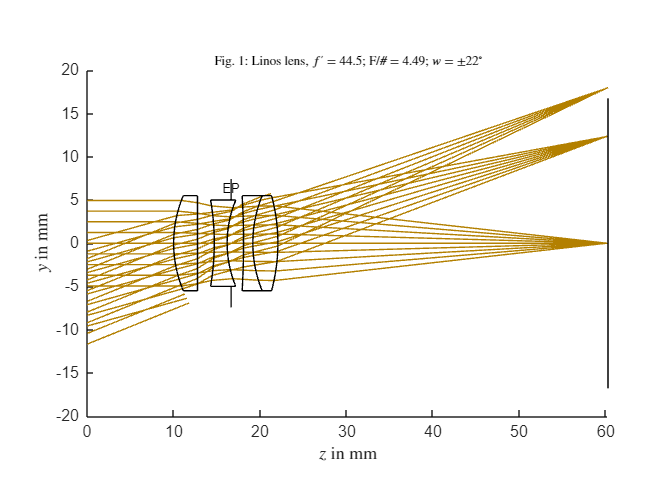

figure()
warning off 
plot_layout_inf(linos_f44,1,3,9);
warning on
axis([0 sum(linos_f44.d(1:linos_f44.n_surf)) -20 20])
xlabel('$z$ in mm','Interpreter','Latex'), ylabel('$y$ in mm','Interpreter','Latex')
title(['Fig. 1: Linos lens, $f''=$', num2str(efl_linos_f44,3), '; F$/\#=$', ...
    num2str(efl_linos_f44/2/linos_f44.l_P,3), '; $w=\pm$', num2str(linos_f44.w/pi*180,3) '$^\circ$'], 'Interpreter', 'latex');

## 1. Ray Tracing

### 1.1. Trace Rays to Image Plane

w=0; % field angle
% w=20/180*pi; 
N_trace_sq=51; % square root of number of rays

r_pos: position of rays, r_dir: directions of rays, OPL: optical path lengths of rays

warning off
[r_pos,r_dir,OPL]=spot_diag_inf(linos_f44, w, N_trace_sq);
warning on 

#### 1.1.1 Display Spot Diagram in Imge Plane

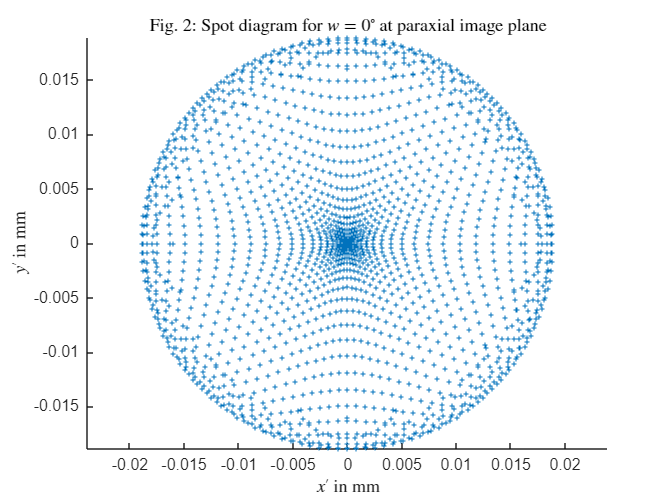

figure()
line(r_pos(1,:),r_pos(2,:), 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3); axis equal
xlabel('$x''$ in mm','Interpreter','Latex'), ylabel('$y''$ in mm','Interpreter','Latex')
title(['Fig. 2: Spot diagram for $w=$' num2str(w/pi*180) '$^\circ$ at paraxial image plane'],'Interpreter','Latex');

Geometrical aberrrations (3rd order) see [ch. 4.11.4.1 Einführung Bildfehler](https://ilias.hs-heilbronn.de/ilias.php?ref_id=67103&obj_id=8294&cmd=layout&cmdClass=illmpresentationgui&cmdNode=fk&baseClass=ilLMPresentationGUI)

#### 1.1.2 Calculate Geometrical OTF from Spot Diagram

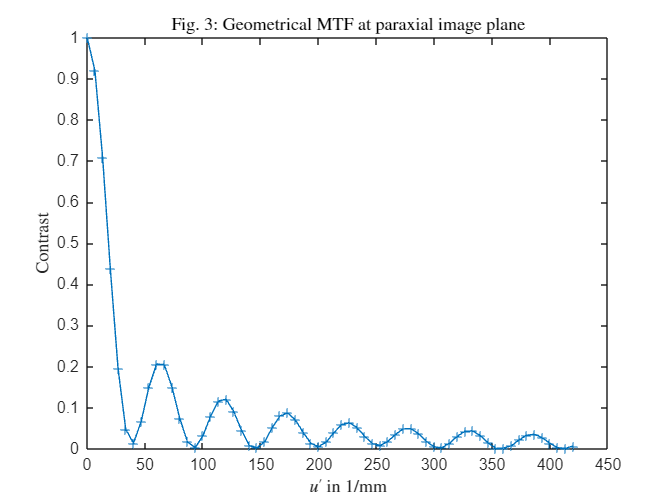

uv_max=2*NA_q/linos_f44.la(1);
N_u=64; % number of spatial frequency samples
dir='x'; % direction in the image plane ('x' or 'y')
[otf_g, u_q_sim]=otf_geom(r_pos,N_u, uv_max, dir); 
if dir == 'x', dir_uv='u'; elseif dir=='y', dir_uv='v'; end

figure()
plot(u_q_sim, abs(otf_g),'Marker', '+')
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel('Contrast','Interpreter','Latex')
title('Fig. 3: Geometrical MTF at paraxial image plane','Interpreter','Latex')

### 1.2 Find Best Image Plane

#### 1.2.1 Calulate OTF for Different Focal Planes

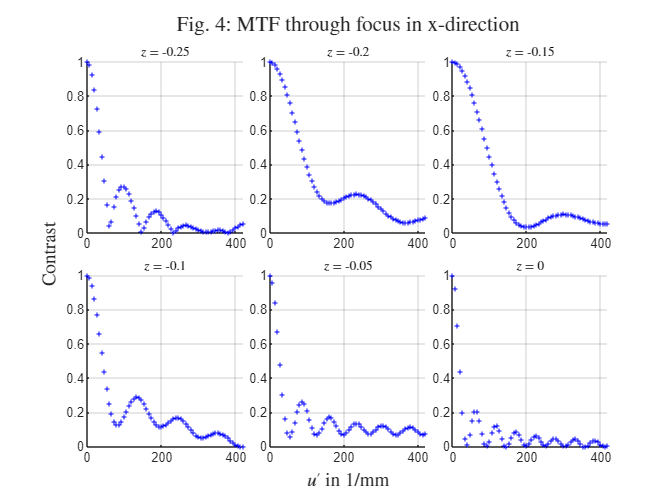

z_min=-0.25; z_max=-0.0;
m_tile=2;n_tile=3;
z_tf=linspace(z_min,z_max,m_tile*n_tile);
[otf_tf, f]=otf_geom_tf(r_pos,r_dir, z_tf, N_u, uv_max, dir);

figure()
t=tiledlayout(m_tile,n_tile,'TileSpacing','Compact');
for i_z=1:m_tile*n_tile
    nexttile
    line(f,abs(otf_tf(i_z,:)),'Color', 'b', 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3)
    set(gca,'ylim',[0 1]); set(gca,'FontSize',8); title(['$z=$', num2str(z_tf(i_z), 3)],'FontSize',8,'Interpreter','latex');
    grid on
end
xlabel(t,['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel(t,'Contrast','Interpreter', 'latex')
title(t,['Fig. 4: MTF through focus in  ' dir '-direction'], 'Interpreter', 'latex')

#### 1.2.2 Find the Best Image Plane along the z-Axis location by Minimum rms-Size of Spot Diagram

if w==0
    dir_rms='xy'; % dir for minimum rms-size ('xy', 'x, or 'y')
else
    dir_rms=dir; % dir for minimum rms-size ('xy', 'x, or 'y')
end
pos_rms=plane_min_rms(r_pos, r_dir, dir_rms); 
d_z=pos_rms(3); % defocus
disp(['Defocus for minimum spot size: ' num2str(d_z,3)])

Defocus for minimum spot size: -0.171


1.2.2.1 Spot Diagram at Found Defocus

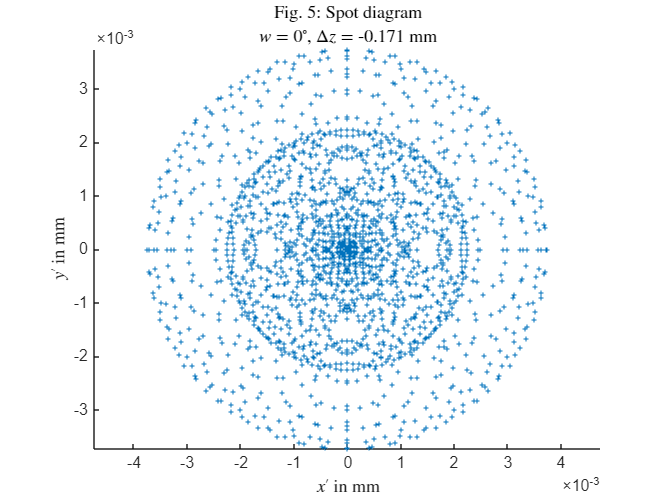

r_dz_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*d_z; % spots at defocus
OPL_dz=OPL+linos_f44.n(linos_f44.n_surf,1)*d_z./r_dir(3,:); 
% set image plane to the desired value:
linos_f44.d(end)=bfl_linos_f44+d_z;

figure()
line(r_dz_pos(1,:),r_dz_pos(2,:), 'LineStyle', 'none', 'Marker', '+', 'MarkerSize',3); axis equal
xlabel('$x''$ in mm','Interpreter','Latex'), ylabel('$y''$ in mm','Interpreter','Latex')
title({['Fig. 5: Spot diagram']; ['$w= $', num2str(w/pi*180), '$^\circ$, $\Delta z=$', num2str(d_z,3), ' mm']},'Interpreter','Latex');

1.2.2.2 Geometrical OTF at Defocs

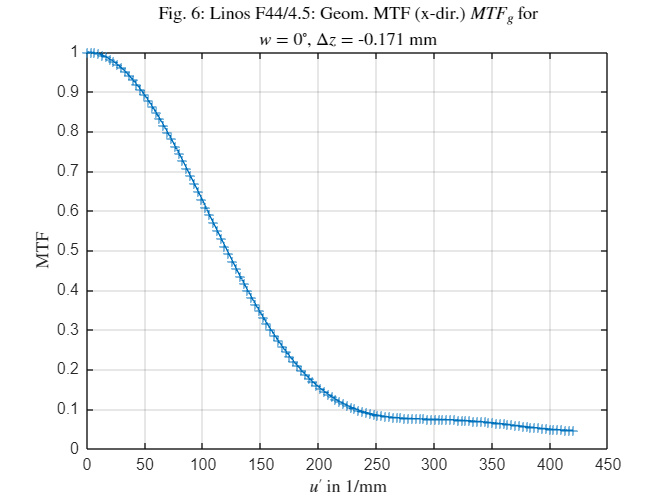

[otf_g_dz, u_q_sim]=otf_geom(r_dz_pos,2*N_u, uv_max, dir);

figure()
plot(u_q_sim, abs(otf_g_dz),'Marker', '+')
set(gca, 'Ylim', [0 1]); xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex'), ylabel('MTF','Interpreter','Latex')
title({['Fig. 6: Linos F44/4.5: Geom. MTF (' dir '-dir.) ' '$MTF_g$' ' for'], ['$w= $' num2str(w/pi*180) '$^\circ$, $\Delta z=$' num2str(d_z,3) ' mm']},'Interpreter','Latex');
grid on

### 1.2 Trace Rays to Exit Pupil including Optical Path Length (OPL)

The OPL (optical path length) of the rays define the wavefront, i.e


$$W=\frac{OPL}{\lambda_0}$$


#### 1.2.1 Find Location of Exit Pupil $P'$ from Given Entrance Pupil

z_Pq=image_distance(linos_f44.d_P-linos_f44.d(1),linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n)+sum(linos_f44.d(1:linos_f44.n_surf-1));
d_PqOq=sum(linos_f44.d(1:linos_f44.n_surf))-z_Pq; % distance from exit pupil to image plane

#### 1.2.2 Trace Rays to Exit Pupil Including OPL

r_Pq_pos=r_dz_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*(-d_PqOq);
OPL_Pq=OPL_dz+linos_f44.n(linos_f44.n_surf,1)*(-d_PqOq)./r_dir(3,:); 

#### 1.2.3 Subtract from OPL Spherical Wave to obtain OPD (optical path difference) to Perfect Image Point

Perfect image point is at y_q = mean(r_dz_pos(2,:)) (x_q=0);

OPD_Pq=OPL_Pq+linos_f44.n(linos_f44.n_surf,1)*...
    sqrt(r_Pq_pos(1,:).^2+(r_Pq_pos(2,:)-mean(r_dz_pos(2,:))).^2+d_PqOq^2);
% subtract constant path length
[min_pos,ind_min_pos]=min(sum(r_Pq_pos(1:2,:).^2));
OPD_Pq=OPD_Pq-OPD_Pq(ind_min_pos);

#### 1.2.4 Interpolate Wavefront on Regular x/y-Grid

1.2.4.1 Define Regular x/y-Grid in Exit Pupil 

An aquidistant (regular) grid is needed for DFT etc.

N=512; % Dimension of the regular grid
if mod(N,2) ~= 0, warning('N not even! indexing is not correct.'), end
y_max=10*max(max(abs(r_Pq_pos(1,:))),max(abs(r_Pq_pos(2,:)))); % +/- height of the amplitude distribution
dy_Pq=2*y_max/N;
y_Pq=((0:N-1)-N/2)*dy_Pq; %y-Koordinaten der AP
x_Pq=((0:N-1)-N/2)*dy_Pq; %x-Koordinaten der AP
[X_Pq,Y_Pq]=meshgrid(x_Pq,y_Pq);

1.2.4.2 Interpolate the OPD data on the Iegular Grid by Cubic Interpolation

OPD_Pq_I=NaN(N);
% grid indices of the exit pupil
ind_Pq_gd_x=find((x_Pq >= min(r_Pq_pos(1,:))) & (x_Pq <= max(r_Pq_pos(1,:)))); 
ind_Pq_gd_y=find((y_Pq >= min(r_Pq_pos(2,:))) & (y_Pq <= max(r_Pq_pos(2,:)))); 
warning off
OPD_Pq_I(ind_Pq_gd_y,ind_Pq_gd_x)=griddata(r_Pq_pos(1,:),r_Pq_pos(2,:),...
    OPD_Pq,X_Pq(ind_Pq_gd_y,ind_Pq_gd_x),Y_Pq(ind_Pq_gd_y,ind_Pq_gd_x), 'cubic');
warning on

### 1.3 Wavefront from OPD

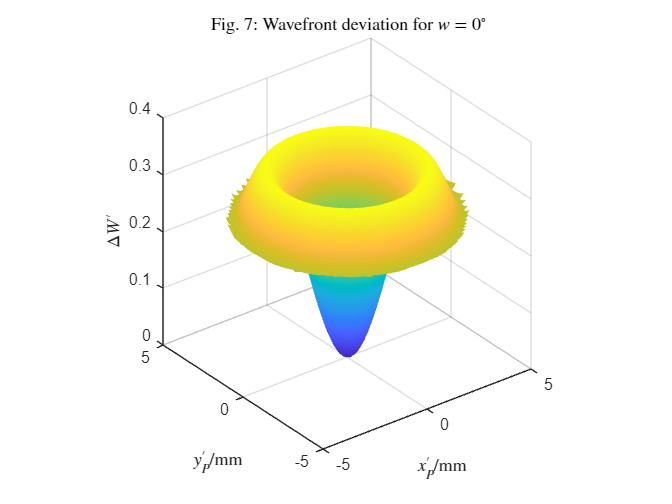

dW_Pq= OPD_Pq_I/linos_f44.la(1);

figure()					
surf(X_Pq,Y_Pq,dW_Pq); shading interp		
title(['Fig. 7: Wavefront deviation for $w = $', num2str(w/pi*180), '$^\circ$'],'Interpreter','Latex'); 						
xlabel('$x''_P$/mm','Interpreter','Latex');	ylabel('$y''_P$/mm','Interpreter','Latex');	zlabel('$\Delta W''$','Interpreter','Latex'); axis square			

## 2. Calculate PSF and OTF from the Wavefront

#### 2.1 Amplitude distribution in the exit pupil from wavefront

Assumption: Homogenous illumination of exit pupil.

A_Pq=zeros(N);
ind_p_q=find(~isnan(dW_Pq));
Tq=1; % homogenous illumination inside of exit pupil
A_Pq(ind_p_q) = Tq*exp(j*2*pi*dW_Pq(ind_p_q));

#### 2.2 Amplitude distribution in the image plane by DFT and PSF

A_q=fftshift(fft2(ifftshift(A_Pq))); 
A_q=A_q/sum(sum(abs(A_Pq))); % normalization to constant power 
PSF=abs(A_q).^2; % irradiance

Cooridnates in the image plane

dy_q=d_PqOq*linos_f44.la(1)/(dy_Pq*N);
y_q=((0:N-1)-N/2)*dy_q;
x_q=((0:N-1)-N/2)*dy_q;

#### 2.3 OTF from PSF by DFT

OTF = fftshift(fft2(ifftshift(PSF))); % calculate OTF by DFT oft PSF
OTF=OTF/sum(sum(abs(PSF))); % normalization

Coordinates in the spatial frequency domain

du_q=1/dy_q/N;
u_q=((0:N-1)-N/2)*du_q;
v_q=((0:N-1)-N/2)*du_q;

#### Profile of OTF

if dir == 'x'
    l_Pq=(max(r_Pq_pos(1,:))-min(r_Pq_pos(1,:)))/2; %Index of limiting spatial frequency
elseif dir == 'y'
    l_Pq=(max(r_Pq_pos(2,:))-min(r_Pq_pos(2,:)))/2;
end
N_max=fix(2*l_Pq/dy_Pq); %Index of limiting spatial frequency
ind_profile=N/2+1:N/2+1+N_max;
if dir == 'x'
    OTF_profile=abs(OTF(N/2+1,ind_profile));
elseif dir == 'y'
    OTF_profile=abs(OTF(ind_profile,N/2+1));
end

u_q_profile=u_q(ind_profile);

#### Comparison with diffraction limited OTF

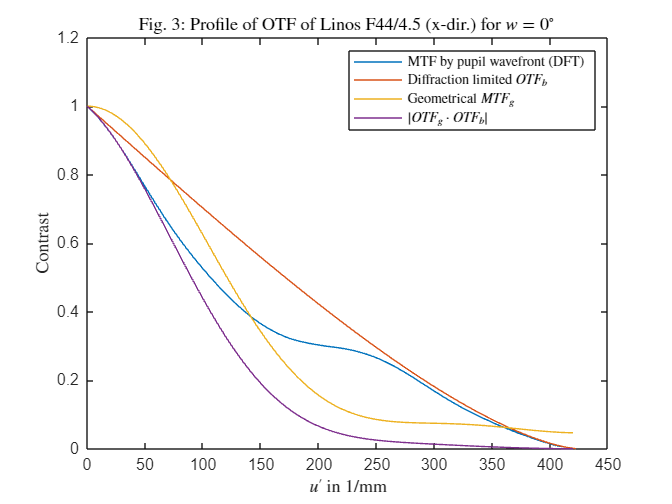

NA_q=l_Pq/d_PqOq;
u_q_max=2*NA_q/linos_f44.la(1);
OTF_b=real(1/pi*(2*acos(abs(u_q_profile)/u_q_max)-sin(2*acos(abs(u_q_profile)/u_q_max)))); % ideal OTF (= FT{Airy})

figure()
plot(u_q_profile,OTF_profile, u_q_profile, OTF_b, ...
    u_q_sim,abs(otf_g_dz), ...
    u_q_sim,abs(otf_g_dz.*real(1/pi*(2*acos(abs(u_q_sim)/u_q_max)-sin(2*acos(abs(u_q_sim)/u_q_max))))))
legend({'MTF by pupil wavefront (DFT)', ...
    'Diffraction limited $OTF_b$', ...
    'Geometrical $MTF_g$', ....
    '$|OTF_g \cdot OTF_b|$'},'Interpreter','Latex')
title({['Fig. 3: Profile of OTF of Linos F44/4.5 (' dir '-dir.) for $w = $', num2str(w/pi*180), '$^\circ$ ']...
    },'Interpreter','Latex')
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex')
ylabel('Contrast','Interpreter','Latex')

## 3. Compare modeled MTF with Measurement

%hold on
%line(36*250/44, 0.5/4*pi, 'Marker','x') % USAF measurement
%hold off

### Adapt Simulation to Measurement set up:

l. 52: Set field angle `w` to same value as in measurement

l. 64: Set direction `dir` to same direction as in measurment (structure which is used for measurement, either horizontal or vertical). Please note: In the simulation, the field always directs in y-direction! This is only relevent for $w \neq 0$.

l. 72: Adapt defocus range to suitable range, if you have changed the field angle.

l. 87-91: Check, if you used the same structure as above for focusing. Otherwise, change `dir_rms` to the direction you used for focusing. 

### Plot Measurement together with simulated MTF by DFT

Plot your measurement (spatial frequencies in image plane together with corrected contrast value) together with simulated MTF (only by DFT). Factor for correction: see later (USAF-target, MTF of sensor).

Please note: $u' = u/m$ ($m:$ magnification, $u:$ spatial frequency in object plane)